# 62743 DSP — Week 13 Tirsdag

% FIR & IIR Highpass Filters (Fourier design + BLT)
clear; close all; clc;

% Add helper functions to path if needed (e.g. plot_s   pectrum.m)
addpath('..\Helpers');

%% ---------- Global parameters & helper switches ----------
Fs   = 2000;               % Sampling frequency [Hz]
Ts   = 1/Fs;               % Sampling interval [s]
fc   = 500;                % Physical cut-off frequency [Hz]
ftil = fc*Ts;              % Normalized digital freq (cycles/sample)
wc   = 2*pi*ftil;          % Digital angular cut-off [rad/sample]

fprintf('Global params:\n');

Global params:


fprintf('  Fs   = %.0f Hz\n', Fs);

  Fs   = 2000 Hz


fprintf('  Ts   = %.4e s\n', Ts);

  Ts   = 5.0000e-04 s


fprintf('  fc   = %.0f Hz\n', fc);

  fc   = 500 Hz


fprintf('  f~   = fc*Ts = %.4f cycles/sample\n', ftil);

  f~   = fc*Ts = 0.2500 cycles/sample


fprintf('  wc   = 2*pi*f~ = %.4f rad/sample (should be pi/2)\n\n', wc);

  wc   = 2*pi*f~ = 1.5708 rad/sample (should be pi/2)




% Folder for saving figures
imgDir   = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images\Week13_Tirsdag';
saveFigs = true;

if saveFigs && ~exist(imgDir,'dir')
    mkdir(imgDir);
end

## Exercise 1-A: Ideal highpass impulse response

% 1) Write expression for h_HP,ideal[n]
%    For an ideal LP: h_LP[n] = sin(wc*n)/(pi*n), n!=0; h_LP[0] = wc/pi
%    Ideal HP by spectral inversion: h_HP[n] = delta[n] - h_LP[n].
%
% 2) Insert filter parameters: wc = pi/2.

fprintf('Exercise 1-A:\n');

Exercise 1-A:



% Show the special values explicitly
hLP0 = wc/pi;        % h_LP[0]
hHP0 = 1 - hLP0;     % h_HP[0] = 1 - wc/pi

fprintf('  h_LP[0] = wc/pi = %.4f\n', hLP0);

  h_LP[0] = wc/pi = 0.5000


fprintf('  h_HP[0] = 1 - wc/pi = %.4f\n\n', hHP0);

  h_HP[0] = 1 - wc/pi = 0.5000



## Exercise 1-B: Plot ideal h_HP[n], n = -30..30; causality & length

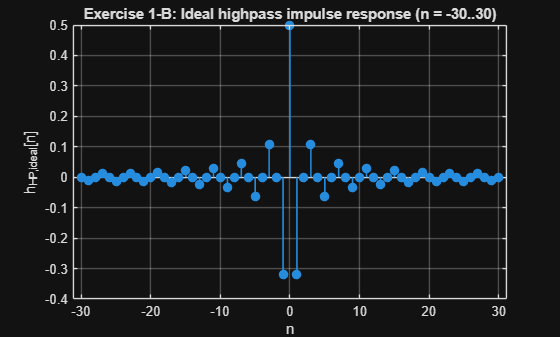

n_ideal = -30:30;

% Ideal lowpass impulse response
hLP_ideal = zeros(size(n_ideal));
idx0      = (n_ideal == 0);
hLP_ideal(idx0)  = wc/pi;
hLP_ideal(~idx0) = sin(wc*n_ideal(~idx0))./(pi*n_ideal(~idx0));

% Ideal highpass via spectral inversion
delta_n          = double(idx0);        % delta[n]
hHP_ideal        = delta_n - hLP_ideal; % ideal HP

% Plot
figure;
stem(n_ideal, hHP_ideal, 'filled', 'LineWidth', 1.2); grid on;
xlabel('n');
ylabel('h_{HP,ideal}[n]');
title('Exercise 1-B: Ideal highpass impulse response (n = -30..30)');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_1B_hp_ideal_impulse.png'), 'Resolution', 300);
end


fprintf('Exercise 1-B:\n');

Exercise 1-B:


fprintf('  Ideal h_HP[n] is non-zero for negative and positive n: NON-CAUSAL.\n');

  Ideal h_HP[n] is non-zero for negative and positive n: NON-CAUSAL.


fprintf('  It is defined for all integer n: IMPULSE RESPONSE IS INFINITE.\n\n');

  It is defined for all integer n: IMPULSE RESPONSE IS INFINITE.



## Exercise 1-C: FIR1 with N_taps = 9 (Fourier design, highpass)

% One of the three FIR filters: N_taps,1 = 9.
%   M = N_taps - 1, K = M/2 (Type I linear-phase, symmetric).
% h_FIR1[n] = h_HP,ideal[n-K], truncated to n = 0..M.

Ntaps1 = 9;
M1     = Ntaps1 - 1;
K1     = M1/2;

fprintf('Exercise 1-C:\n');

Exercise 1-C:


fprintf('  FIR1: N_taps = %d, M = %d, K = %d\n', Ntaps1, M1, K1);

  FIR1: N_taps = 9, M = 8, K = 4



% Symmetric index around 0 for ideal impulse response
n_sym1     = -K1:K1;             % length 9
hLP_sym1   = zeros(size(n_sym1));
idx0_sym   = (n_sym1 == 0);
hLP_sym1(idx0_sym)   = wc/pi;
hLP_sym1(~idx0_sym)  = sin(wc*n_sym1(~idx0_sym))./(pi*n_sym1(~idx0_sym));

delta_sym1          = double(idx0_sym);
hHP_sym1            = delta_sym1 - hLP_sym1;   % ideal HP, symmetric
b_FIR1              = hHP_sym1;                % causal coeffs n=0..M1
a_FIR1              = 1;

fprintf('  FIR1 coefficients b_FIR1 (n = 0..M):\n');

  FIR1 coefficients b_FIR1 (n = 0..M):


disp(b_FIR1.');

    0.0000
    0.1061
   -0.0000
   -0.3183
    0.5000
   -0.3183
   -0.0000
    0.1061
    0.0000




% Transfer function H_FIR1(z) = sum_{n=0}^M b[n] z^{-n}
fprintf('  H_FIR1(z) = sum_{n=0}^{%d} b_FIR1[n] z^{-n}\n\n', M1);

  H_FIR1(z) = sum_{n=0}^{8} b_FIR1[n] z^{-n}



## Exercise 1-D: Plot impulse response of FIR1, causality & length

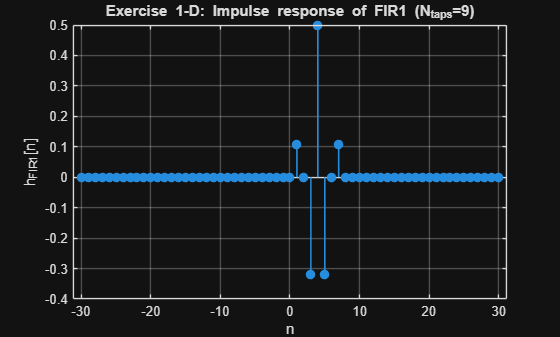


n_plot1 = -30:30;
h_plot1 = zeros(size(n_plot1));
idx_valid = (n_plot1 >= 0 & n_plot1 <= M1);
h_plot1(idx_valid) = b_FIR1(n_plot1(idx_valid)+1);  % shift index

figure;
stem(n_plot1, h_plot1, 'filled', 'LineWidth', 1.2); grid on;
xlabel('n');
ylabel('h_{FIR1}[n]');
title('Exercise 1-D: Impulse response of FIR1 (N_{taps}=9)');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_1D_FIR1_impulse.png'), 'Resolution', 300);
end


fprintf('Exercise 1-D:\n');

Exercise 1-D:


fprintf('  FIR1 impulse response is non-zero only for 0 <= n <= %d => CAUSAL.\n', M1);

  FIR1 impulse response is non-zero only for 0 <= n <= 8 => CAUSAL.


fprintf('  It has exactly N_taps = %d non-zero samples => FINITE length.\n\n', Ntaps1);

  It has exactly N_taps = 9 non-zero samples => FINITE length.



## Exercise 1-E: freqz for FIR1; magnitude & phase; fc marking

fprintf('Exercise 1-E:\n');

Exercise 1-E:


fprintf('  freqz(b,a,1024,Fs) returns H(k) and F(k) in Hz.\n');

  freqz(b,a,1024,Fs) returns H(k) and F(k) in Hz.


fprintf('  b = numerator FIR coeffs, a = denominator (for FIR: a=[1]).\n\n');

  b = numerator FIR coeffs, a = denominator (for FIR: a=[1]).



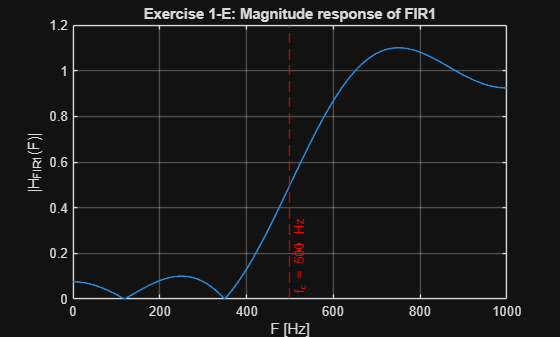


[H1,F1] = freqz(b_FIR1, a_FIR1, 1024, Fs);

% Magnitude response
figure;
plot(F1, abs(H1), 'LineWidth', 1.2); grid on; hold on;
xline(fc, '--r', sprintf('f_c = %d Hz', fc), ...
    'LabelVerticalAlignment','bottom');
xlabel('F [Hz]');
ylabel('|H_{FIR1}(F)|');
title('Exercise 1-E: Magnitude response of FIR1');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_1E_FIR1_mag.png'), 'Resolution', 300);
end

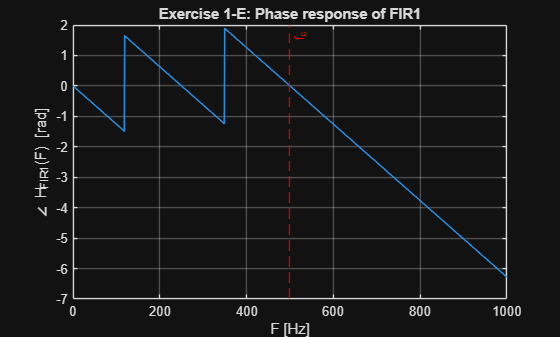


% Phase response
figure;
plot(F1, unwrap(angle(H1)), 'LineWidth', 1.2); grid on; hold on;
xline(fc, '--r', 'f_c');
xlabel('F [Hz]');
ylabel('\angle H_{FIR1}(F) [rad]');
title('Exercise 1-E: Phase response of FIR1');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_1E_FIR1_phase.png'), 'Resolution', 300);
end


fprintf('  Physical cut-off frequency from normalized f~ = 0.25:\n');

  Physical cut-off frequency from normalized f~ = 0.25:


fprintf('    F_c = f~ * Fs = 0.25 * 2000 = 500 Hz (matches figure marking).\n\n');

    F_c = f~ * Fs = 0.25 * 2000 = 500 Hz (matches figure marking).



## Exercise 1-F: FIR2 & FIR3 (N_taps = 19, 29) and comparison

Ntaps2 = 19;       % FIR2
M2     = Ntaps2 - 1;
K2     = M2/2;

Ntaps3 = 29;       % FIR3
M3     = Ntaps3 - 1;
K3     = M3/2;

fprintf('Exercise 1-F:\n');

Exercise 1-F:


fprintf('  FIR2: N_taps = %d, M = %d, K = %d\n', Ntaps2, M2, K2);

  FIR2: N_taps = 19, M = 18, K = 9


fprintf('  FIR3: N_taps = %d, M = %d, K = %d\n\n', Ntaps3, M3, K3);

  FIR3: N_taps = 29, M = 28, K = 14



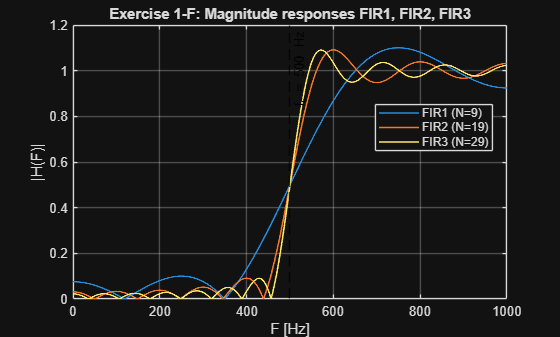


% FIR2
n_sym2    = -K2:K2;
hLP_sym2  = zeros(size(n_sym2));
idx0_2    = (n_sym2 == 0);
hLP_sym2(idx0_2)   = wc/pi;
hLP_sym2(~idx0_2)  = sin(wc*n_sym2(~idx0_2))./(pi*n_sym2(~idx0_2));
delta_sym2         = double(idx0_2);
hHP_sym2           = delta_sym2 - hLP_sym2;
b_FIR2             = hHP_sym2;
a_FIR2             = 1;

% FIR3
n_sym3    = -K3:K3;
hLP_sym3  = zeros(size(n_sym3));
idx0_3    = (n_sym3 == 0);
hLP_sym3(idx0_3)   = wc/pi;
hLP_sym3(~idx0_3)  = sin(wc*n_sym3(~idx0_3))./(pi*n_sym3(~idx0_3));
delta_sym3         = double(idx0_3);
hHP_sym3           = delta_sym3 - hLP_sym3;
b_FIR3             = hHP_sym3;
a_FIR3             = 1;

% Magnitude responses (same frequency grid)
[H2,Fresp] = freqz(b_FIR2, a_FIR2, 2048, Fs);
H3         = freqz(b_FIR3, a_FIR3, 2048, Fs);
H1_long    = freqz(b_FIR1, a_FIR1, 2048, Fs);

figure;
plot(Fresp, abs(H1_long), 'LineWidth', 1.2); hold on;
plot(Fresp, abs(H2), 'LineWidth', 1.2);
plot(Fresp, abs(H3), 'LineWidth', 1.2);
grid on;
xline(fc, '--k', 'f_c = 500 Hz');
xlabel('F [Hz]');
ylabel('|H(F)|');
title('Exercise 1-F: Magnitude responses FIR1, FIR2, FIR3');
legend('FIR1 (N=9)','FIR2 (N=19)','FIR3 (N=29)','Location','best');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_1F_FIR123_mag.png'), 'Resolution', 300);
end


fprintf('  Increasing N_taps (9 -> 19 -> 29) makes transition band sharper\n');

  Increasing N_taps (9 -> 19 -> 29) makes transition band sharper


fprintf('  and stopband attenuation higher, as seen in the overlaid responses.\n\n');

  and stopband attenuation higher, as seen in the overlaid responses.



## Exercise 2: IIR highpass via BLT (Butterworth prototype)

% Filter specs:
%   Design method: BLT (alpha = 2/Ts)
%   Fs = 2000 Hz
%   Normalized digital passband freq: f~_p = 500 Hz * Ts = 0.25
%   Analog prototype: 4th order Butterworth, epsilon = 1


%% Exercise 2-A: Analog filter characteristics via BLT
fprintf('Exercise 2-A:\n');

Exercise 2-A:



fp_tilde = fc * Ts;            % normalized digital passband freq (0.25)
wp       = 2*pi*fp_tilde;      % digital angular passband freq [rad/sample]

alphaBLT = 2/Ts;               % alpha = 2/Ts
Omega_p  = alphaBLT * tan(wp/2);   % prewarped analog passband [rad/s]
Fp_analog = Omega_p / (2*pi);      % analog passband in Hz

fprintf('  Digital passband: f~_p = %.4f, w_p = %.4f rad/sample\n', ...
        fp_tilde, wp);

  Digital passband: f~_p = 0.2500, w_p = 1.5708 rad/sample


fprintf('  Prewarped analog passband: Omega_p = %.4f rad/s\n', Omega_p);

  Prewarped analog passband: Omega_p = 4000.0000 rad/s


fprintf('  Corresponding F_p (analog) = %.2f Hz\n\n', Fp_analog);

  Corresponding F_p (analog) = 636.62 Hz




% Analog lowpass *prototype* (normalized 4th-order Butterworth, cutoff = 1 rad/s)
n_proto = 4;
[b_lp, a_lp] = butter(n_proto, 1, 's');


fprintf('  Prototype analog LP transfer H_LP(s) = B_LP(s) / A_LP(s)\n');

  Prototype analog LP transfer H_LP(s) = B_LP(s) / A_LP(s)


disp('  Numerator B_LP(s) coefficients:'); disp(b_lp.');

  Numerator B_LP(s) coefficients:
     0
     0
     0
     0
     1



disp('  Denominator A_LP(s) coefficients:'); disp(a_lp.');

  Denominator A_LP(s) coefficients:
    1.0000
    2.6131
    3.4142
    2.6131
    1.0000



## Exercise 2-B: Analog highpass transfer function H_HP(s)

fprintf('Exercise 2-B:\n');

Exercise 2-B:



% Use lp2hp to convert normalized LP -> HP with cutoff Omega_p
[b_hp, a_hp] = lp2hp(b_lp, a_lp, Omega_p);

disp('  Highpass analog transfer H_HP(s) = B_HP(s) / A_HP(s)');

  Highpass analog transfer H_HP(s) = B_HP(s) / A_HP(s)


disp('  Numerator B_HP(s) coefficients (beta):');  disp(b_hp.');

  Numerator B_HP(s) coefficients (beta):
    1.0000
    0.0000
    0.0000
    0.0000
   -0.0000



disp('  Denominator A_HP(s) coefficients (alpha):'); disp(a_hp.');

  Denominator A_HP(s) coefficients (alpha):
   1.0e+14 *

    0.0000
    0.0000
    0.0000
    0.0017
    2.5600




fprintf('  For this even-order HP, alpha_0 = Omega_p^4 (up to normalization).\n\n');

  For this even-order HP, alpha_0 = Omega_p^4 (up to normalization).



## Exercise 2-C: Analog magnitude response |H(jΩ)| vs F (Hz)

fprintf('Exercise 2-C (corrected):\n');

Exercise 2-C (corrected):


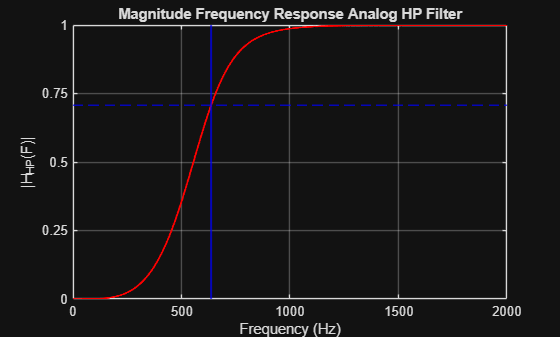


% 1) Linear frequency axis in Hz
F_axis = linspace(0, 2000, 2000);     % 0 → 2000 Hz

% 2) Convert to angular frequency (rad/s)
Omega_axis = 2*pi*F_axis;

% 3) Evaluate analog HP response
H_analog = freqs(b_hp, a_hp, Omega_axis);

% 4) Plot magnitude
figure;
plot(F_axis, abs(H_analog), 'r', 'LineWidth', 1.4); hold on; grid on;

% Mark Fp (in Hz)
xline(Fp_analog, 'b', 'LineWidth', 1.5);

% Mark Butterworth level 1/sqrt(2)
yline(1/sqrt(2), '--b', 'LineWidth', 1.2);

yticks([0 0.25 0.5 0.75 1]);


xlabel('Frequency (Hz)');
ylabel('|H_{HP}(F)|');
title('Magnitude Frequency Response Analog HP Filter');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_2C_analog_HP_mag.png'), 'Resolution', 300);
end

## Exercise 2-D: Digital HP via bilinear transform, H(z)

fprintf('Exercise 2-D:\n');

Exercise 2-D:



% Digital highpass via bilinear transform
[b_z, a_z] = bilinear(b_hp, a_hp, Fs);   % maps analog HP -> digital HP


disp('  Digital HP H(z) = B(z) / A(z)');

  Digital HP H(z) = B(z) / A(z)


disp('  Numerator B(z) coeffs b_z:'); disp(b_z.');

  Numerator B(z) coeffs b_z:
    0.0940
   -0.3759
    0.5639
   -0.3759
    0.0940



disp('  Denominator A(z) coeffs a_z:'); disp(a_z.');

  Denominator A(z) coeffs a_z:
    1.0000
   -0.0000
    0.4860
    0.0000
    0.0177




fprintf('  Transfer function:\n');

  Transfer function:


fprintf('    H(z) = (b_0 + b_1 z^{-1} + ... + b_M z^{-M}) / ');

    H(z) = (b_0 + b_1 z^{-1} + ... + b_M z^{-M}) / 

fprintf('(1 + a_1 z^{-1} + ... + a_N z^{-N})\n\n');

(1 + a_1 z^{-1} + ... + a_N z^{-N})



## Exercise 2-E: Difference equation & structure (from b_z, a_z)

fprintf('Exercise 2-E:\n');

Exercise 2-E:



Nnum = numel(b_z) - 1;   % order numerator
Nden = numel(a_z) - 1;   % order denominator

fprintf('  Difference equation (Direct Form I / II):\n');

  Difference equation (Direct Form I / II):


fprintf('    y[n] = ');

    y[n] = 

for k = 0:Nnum
    if k == 0
        fprintf('b_0 x[n]');
    else
        fprintf(' + b_%d x[n-%d]', k, k);
    end
end

b_0 x[n]

 + b_1 x[n-1] + b_2 x[n-2] + b_3 x[n-3] + b_4 x[n-4]

for k = 1:Nden
    fprintf(' - a_%d y[n-%d]', k, k);
end

 - a_1 y[n-1] - a_2 y[n-2] - a_3 y[n-3] - a_4 y[n-4]

fprintf('\n\n');

fprintf('  With the coefficient vectors printed above, this defines\n');

  With the coefficient vectors printed above, this defines


fprintf('  a canonical IIR direct-form structure (either DF-I or DF-II).\n\n');

  a canonical IIR direct-form structure (either DF-I or DF-II).



## Exercise 2-F: Digital HP magnitude via freqz, mark passband edge

fprintf('Exercise 2-F:\n');

Exercise 2-F:


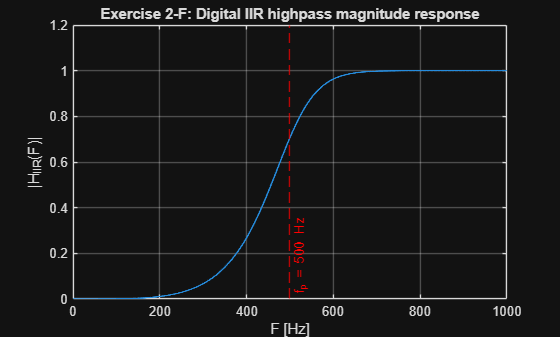


[H_iir, F_iir] = freqz(b_z, a_z, 2048, Fs);

figure;
plot(F_iir, abs(H_iir), 'LineWidth', 1.2); grid on; hold on;
xline(fc, '--r', sprintf('f_p = %d Hz', fc), ...
    'LabelVerticalAlignment','bottom');
xlabel('F [Hz]');
ylabel('|H_{IIR}(F)|');
title('Exercise 2-F: Digital IIR highpass magnitude response');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_2F_IIR_HP_mag.png'), 'Resolution', 300);
end


fprintf('  The Matlab freqz call uses b_z (numerator) and a_z (denominator)\n');

  The Matlab freqz call uses b_z (numerator) and a_z (denominator)


fprintf('  to compute the digital frequency response H(e^{j\omega}).\n\n');

  to compute the digital frequency response H(e^{j

## Exercise 2-G: Compare FIR (FIR1–3) vs IIR HP filters

fprintf('Exercise 2-G:\n');

Exercise 2-G:


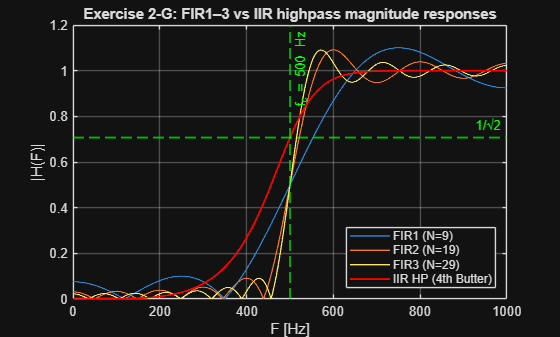


% Compute FIR and IIR responses on the same grid
[H1_cmp, Fcmp] = freqz(b_FIR1, a_FIR1, 2048, Fs);
H2_cmp         = freqz(b_FIR2, a_FIR2, 2048, Fs);
H3_cmp         = freqz(b_FIR3, a_FIR3, 2048, Fs);
H_iir_cmp      = freqz(b_z, a_z, 2048, Fs);

figure;
plot(Fcmp, abs(H1_cmp), 'LineWidth', 1.0); hold on;
plot(Fcmp, abs(H2_cmp), 'LineWidth', 1.0);
plot(Fcmp, abs(H3_cmp), 'LineWidth', 1.0);
plot(Fcmp, abs(H_iir_cmp), 'r', 'LineWidth', 1.4);
grid on;

% Mark cutoff frequency
xline(fc, '--g', 'f_c = 500 Hz', 'LineWidth', 1.3);

% Mark Butterworth level at 1/sqrt(2)
yline(1/sqrt(2), '--g', '1/\surd2', 'LineWidth', 1.4);

xlabel('F [Hz]');
ylabel('|H(F)|');
title('Exercise 2-G: FIR1–3 vs IIR highpass magnitude responses');

legend('FIR1 (N=9)', 'FIR2 (N=19)', 'FIR3 (N=29)', ...
       'IIR HP (4th Butter)', ...
       'Location', 'southeast');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_U13_Tirsdag_2G_FIR_vs_IIR_mag.png'), 'Resolution', 300);
end


fprintf('  FIR filters: linear phase, finite impulse response, but wider\n');

  FIR filters: linear phase, finite impulse response, but wider


fprintf('  transition band for small N. Increasing N sharpens transition.\n');

  transition band for small N. Increasing N sharpens transition.


fprintf('  IIR filter: much sharper transition for same approximate order,\n');

  IIR filter: much sharper transition for same approximate order,


fprintf('  but non-linear phase and theoretically infinite impulse response.\n\n');

  but non-linear phase and theoretically infinite impulse response.




fprintf('Done: all sub-exercises for Uge 13 – Tirsdag evaluated.\n');

Done: all sub-exercises for Uge 13 – Tirsdag evaluated.
